%% Clear workspace and initialize
clc; clear; close all;
rng(42); % For reproducible results

%% 1. Generate Workload (1000 processes)
num_processes = 1000;
burst_times = 5 + 15*rand(num_processes,1); % Uniform(5-20ms)
io_prob = 0.1*rand(num_processes,1);        % I/O probability (0-10%)
arrival_times = cumsum(0.2*rand(num_processes,1)); % Staggered arrivals

% System conditions (simulated variability)
cpu_usage = 40 + 30*rand();    % 40-70% CPU
memory_usage = 50 + 20*rand(); % 50-70% memory
io_bytes = 1e6 + 9e6*rand();   % 1-10MB/s I/O
ctx_switches = 1000 + 2000*rand(); % 1000-3000 ctx switches/sec

%% 2. Traditional RR Simulation (Fixed TQ=10ms)
fprintf('Running Traditional RR...\n');

Running Traditional RR...


tq_fixed = 10;
[~, turnaround_fixed, waiting_fixed, throughput_fixed, ctx_fixed] = ...
    rr_simulator(burst_times, io_prob, arrival_times, tq_fixed);

%% 3. MLR-Optimized RR Simulation
fprintf('Running MLR-Optimized RR...\n');

Running MLR-Optimized RR...


load('enhanced_rr_mlr_model.mat', 'mdl'); % Your trained model

% Predict dynamic TQ
X_new = [cpu_usage, num_processes, io_bytes, ctx_switches, memory_usage];
tq_mlr = predict(mdl, X_new);
tq_mlr = max(5, min(50, tq_mlr)); % Constrain to 5-50ms

[~, turnaround_mlr, waiting_mlr, throughput_mlr, ctx_mlr] = ...
    rr_simulator(burst_times, io_prob, arrival_times, tq_mlr);

%% 4. Calculate Performance Metrics
metrics = struct();
metrics.Turnaround.Fixed = mean(turnaround_fixed);
metrics.Turnaround.MLR = mean(turnaround_mlr);
metrics.Turnaround.Improvement = (metrics.Turnaround.Fixed - metrics.Turnaround.MLR)/metrics.Turnaround.Fixed*100;

metrics.Waiting.Fixed = mean(waiting_fixed);
metrics.Waiting.MLR = mean(waiting_mlr);
metrics.Waiting.Improvement = (metrics.Waiting.Fixed - metrics.Waiting.MLR)/metrics.Waiting.Fixed*100;

metrics.Throughput.Fixed = throughput_fixed(end)/arrival_times(end)*1000;
metrics.Throughput.MLR = throughput_mlr(end)/arrival_times(end)*1000;
metrics.Throughput.Improvement = (metrics.Throughput.MLR - metrics.Throughput.Fixed)/metrics.Throughput.Fixed*100;

metrics.ContextSwitches.Fixed = ctx_fixed;
metrics.ContextSwitches.MLR = ctx_mlr;
metrics.ContextSwitches.Improvement = (ctx_fixed - ctx_mlr)/ctx_fixed*100;

%% 5. Display Results
fprintf('\n=========== Performance Comparison ===========\n');


=========== Performance Comparison ===========


fprintf('                   Fixed TQ    MLR TQ    Improvement\n');

                   Fixed TQ    MLR TQ    Improvement


fprintf('                   ---------   -------   -----------\n');

                   ---------   -------   -----------


fprintf('Avg Turnaround:    %7.1f ms  %6.1f ms     +%.1f%%\n', ...
        metrics.Turnaround.Fixed, metrics.Turnaround.MLR, metrics.Turnaround.Improvement);

Avg Turnaround:     8609.6 ms  6778.3 ms     +21.3%


fprintf('Avg Waiting:       %7.1f ms  %6.1f ms     +%.1f%%\n', ...
        metrics.Waiting.Fixed, metrics.Waiting.MLR, metrics.Waiting.Improvement);

Avg Waiting:        8313.4 ms  6143.5 ms     +26.1%


fprintf('Throughput:        %7.1f/s   %6.1f/s      +%.1f%%\n', ...
        metrics.Throughput.Fixed, metrics.Throughput.MLR, metrics.Throughput.Improvement);

Throughput:         9952.1/s   9952.1/s      +0.0%


fprintf('Context Switches:  %7d    %6d       +%.1f%%\n', ...
        metrics.ContextSwitches.Fixed, metrics.ContextSwitches.MLR, metrics.ContextSwitches.Improvement);

Context Switches:     1720      1047       +39.1%


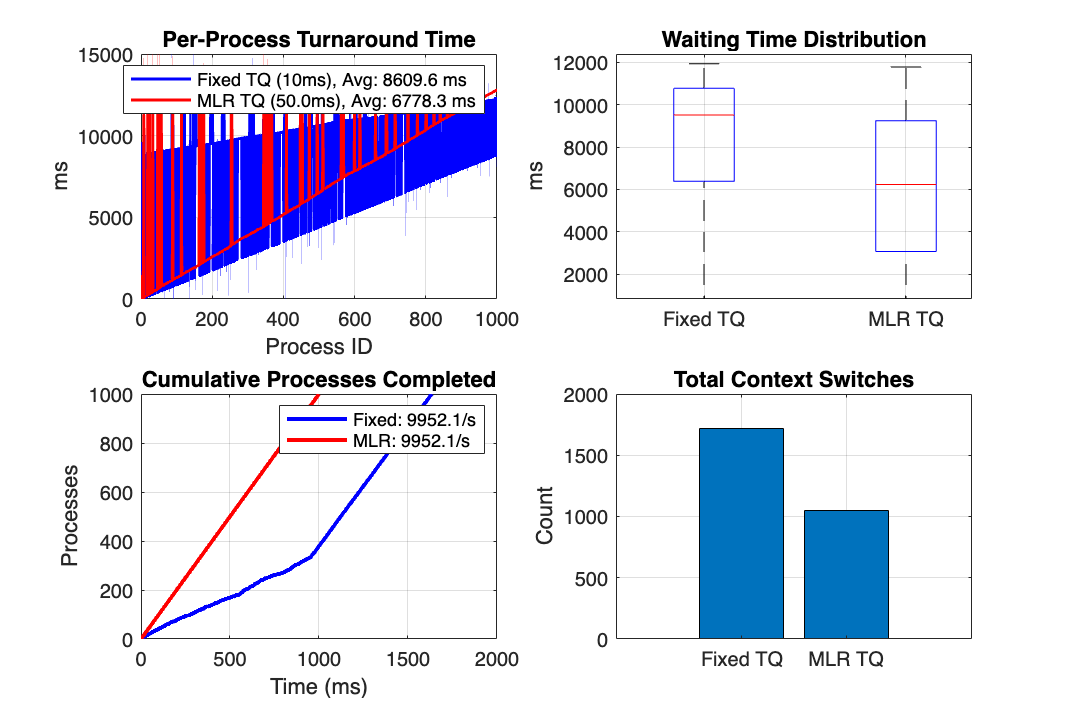


%% 6. Visualizations
figure('Position', [100 100 1200 800]);

% Turnaround Time Comparison
subplot(2,2,1);
plot(turnaround_fixed, 'b', 'LineWidth', 1.5); hold on;
plot(turnaround_mlr, 'r', 'LineWidth', 1.5);
title('Per-Process Turnaround Time');
xlabel('Process ID'); ylabel('ms');
legend(['Fixed TQ (10ms), Avg: ', num2str(metrics.Turnaround.Fixed,'%.1f'),' ms'], ...
       ['MLR TQ (',num2str(tq_mlr,'%.1f'),'ms), Avg: ', num2str(metrics.Turnaround.MLR,'%.1f'),' ms']);
grid on;

% Waiting Time Comparison
subplot(2,2,2);
boxplot([waiting_fixed, waiting_mlr], 'Labels', {'Fixed TQ', 'MLR TQ'});
title('Waiting Time Distribution');
ylabel('ms');
grid on;

% Throughput Over Time
subplot(2,2,3);
plot(throughput_fixed, 'b', 'LineWidth', 2); hold on;
plot(throughput_mlr, 'r', 'LineWidth', 2);
title('Cumulative Processes Completed');
xlabel('Time (ms)'); ylabel('Processes');
legend(['Fixed: ',num2str(metrics.Throughput.Fixed,'%.1f'),'/s'], ...
       ['MLR: ',num2str(metrics.Throughput.MLR,'%.1f'),'/s']);
grid on;

% Context Switches
subplot(2,2,4);
bar([ctx_fixed, ctx_mlr]);
set(gca, 'XTickLabel', {'Fixed TQ', 'MLR TQ'});
title('Total Context Switches');
ylabel('Count');
grid on;


%% RR Simulator Function (Fixed Version)
function [tq_used, turnaround, waiting, throughput, ctx_switches] = ...
         rr_simulator(burst_times, io_prob, arrival_times, tq)
    
    n = length(burst_times);
    remaining = burst_times;
    waiting = zeros(n,1);
    turnaround = zeros(n,1);
    completed = false(n,1);
    current_time = 0;
    throughput = [];
    ctx_switches = 0;
    queue = [];
    
    while ~all(completed)
        % Add newly arrived processes (SAFE VERSION)
        new_arrivals = find(arrival_times <= current_time & ~completed);
        new_arrivals = setdiff(new_arrivals, queue); % Avoid duplicates
        queue = [queue; new_arrivals(:)]; % Ensure column vector
        
        if isempty(queue)
            current_time = min(arrival_times(~completed));
            continue;
        end
        
        % Get next process (SAFE POP)
        pid = queue(1);
        queue(1) = [];
        ctx_switches = ctx_switches + 1;
        
        % Simulate I/O interrupts
        if rand() < io_prob(pid)
            io_time = 0.5*tq;
            remaining(pid) = max(0, remaining(pid) - io_time);
            current_time = current_time + io_time;
            queue(end+1) = pid; % Requeue safely
            continue;
        end
        
        % Execute process
        exec_time = min(tq, remaining(pid));
        remaining(pid) = remaining(pid) - exec_time;
        current_time = current_time + exec_time;
        
        % Update waiting times (SAFE VERSION)
        active_processes = find(arrival_times <= current_time & ~completed);
        other_processes = setdiff(active_processes, pid);
        waiting(other_processes) = waiting(other_processes) + exec_time;
        
        % Check completion
        if remaining(pid) <= 0
            completed(pid) = true;
            turnaround(pid) = current_time - arrival_times(pid);
        else
            queue(end+1) = pid; % Safe requeue
        end
        
        throughput = [throughput; sum(completed)];
    end
    tq_used = tq;
end